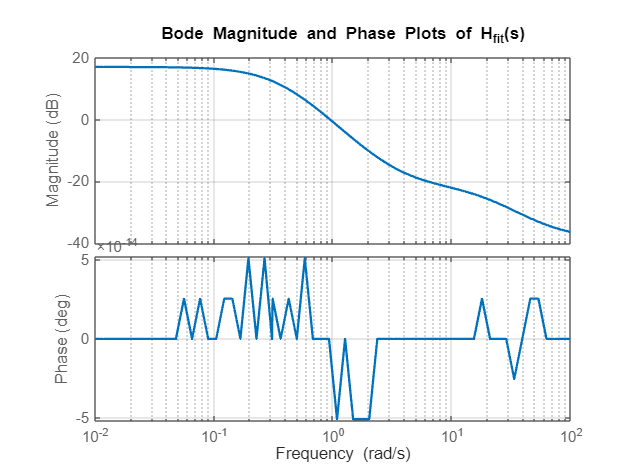

%% Compare Bode (freq response) of two discrete TFs
clc; clear; close all;

% ----------------- User settings -----------------
Fs = 10;           % sampling frequency [Hz] (set to your data Fs)
Ts = 1/Fs;

nfft = 4096;       % frequency samples for plotting

% ----------------- Original discrete TF (z^-1 form) -----------------
b_orig = [0.02679, -0.05951, 0.01895, 0.03348, -0.01971];
a_orig = [1, -3.952, 5.857, -3.857, 0.9523];

% Create discrete TF using z^-1 variable (sample time Ts)
H_orig = tf(b_orig, a_orig, Ts, 'variable','z^-1');

% ----------------- Fitted continuous TF -> discretize with Tustin -----------------
% (use your fitted continuous TF coefficients here)
% Continuous H_fit(s) = (0.01197 s^4 - 40.03 s^2 + 461.3) / (s^4 - 482.7 s^2 + 65.13)
s = tf('s');
Hc_fit = (0.01197*s^4 - 40.03*s^2 + 461.3) / (s^4 - 482.7*s^2 + 65.13);

% Discretize using bilinear (Tustin)
H_fit_d = c2d(Hc_fit, Ts, 'tustin');

% Get numerator/denominator as vectors (z^-1 form) for freqz if needed
[b_fit_d, a_fit_d] = tfdata(H_fit_d, 'v');  % returns in descending z powers but freqz accepts them

% ----------------- Frequency response (Hz axis) -----------------
% Use freqz on digital filter coefficients (freqz expects numerator/den denominator in z^-1 form)
% But tfdata with 'v' returns polynomials in z^-1 for discrete TFs created with 'z^-1' variable;
% if not, ensure you pass correct b,a to freqz.

% compute frequency vector (Hz)
[H1, w] = freqz(b_orig, a_orig, nfft, Fs);   % returns frequency response at frequencies corresponding to Fs
[H2, ~] = freqz(b_fit_d, a_fit_d, nfft, Fs); % fitted discrete TF response

f = w;  % w already in Hz because we used freqz(...,Fs)

%% --- Bode Plot (Magnitude and Phase) ---
figure('Name','Bode Plot of Continuous-Time Fitted TF','NumberTitle','off');
bode(Hc_fit, {1e-2, 1e2});  % frequency range from 0.01 to 100 rad/s
grid on;

% Improve formatting
title('Bode Magnitude and Phase Plots of H_{fit}(s)');
set(findall(gcf,'type','line'),'LineWidth',1.5); % thicker lines

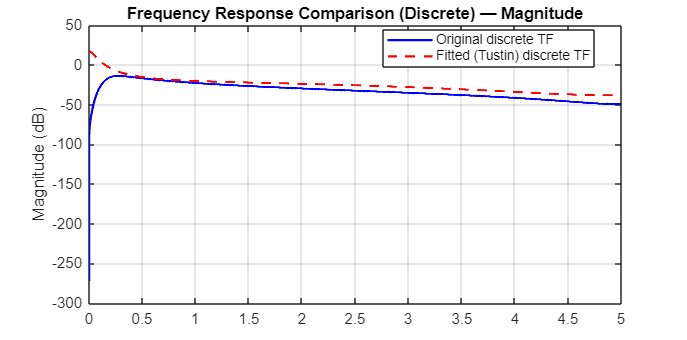



% ----------------- Plot magnitude (dB) and phase (deg) -----------------
figure('Units','normalized','Position',[0.08 0.12 0.82 0.72]);

plot(f, 20*log10(abs(H1)+eps), 'b', 'LineWidth', 1.5); hold on;
plot(f, 20*log10(abs(H2)+eps), 'r--', 'LineWidth', 1.5);
xlim([0 Fs/2]);
ylabel('Magnitude (dB)');
title('Frequency Response Comparison (Discrete) — Magnitude');
legend('Original discrete TF','Fitted (Tustin) discrete TF','Location','best');
grid on;



% ----------------- Poles & zeros / stability check -----------------






